# Create and Customize Stem Plots

Stem plots the data sequence, `Y`, as stems that extend from a baseline along the *x*-axis. The data values are indicated by circles terminating each stem.

### Create a Vector to Plot

Define a single vector `Y `as a set of values from $-2\pi$ to $2\pi$ to plot.

Y = linspace(-2*pi,2*pi,50);

### Basic Stem Plot

Plot the vector `Y `using stem. Each point is plotted at it's index interger value along the x-axis.

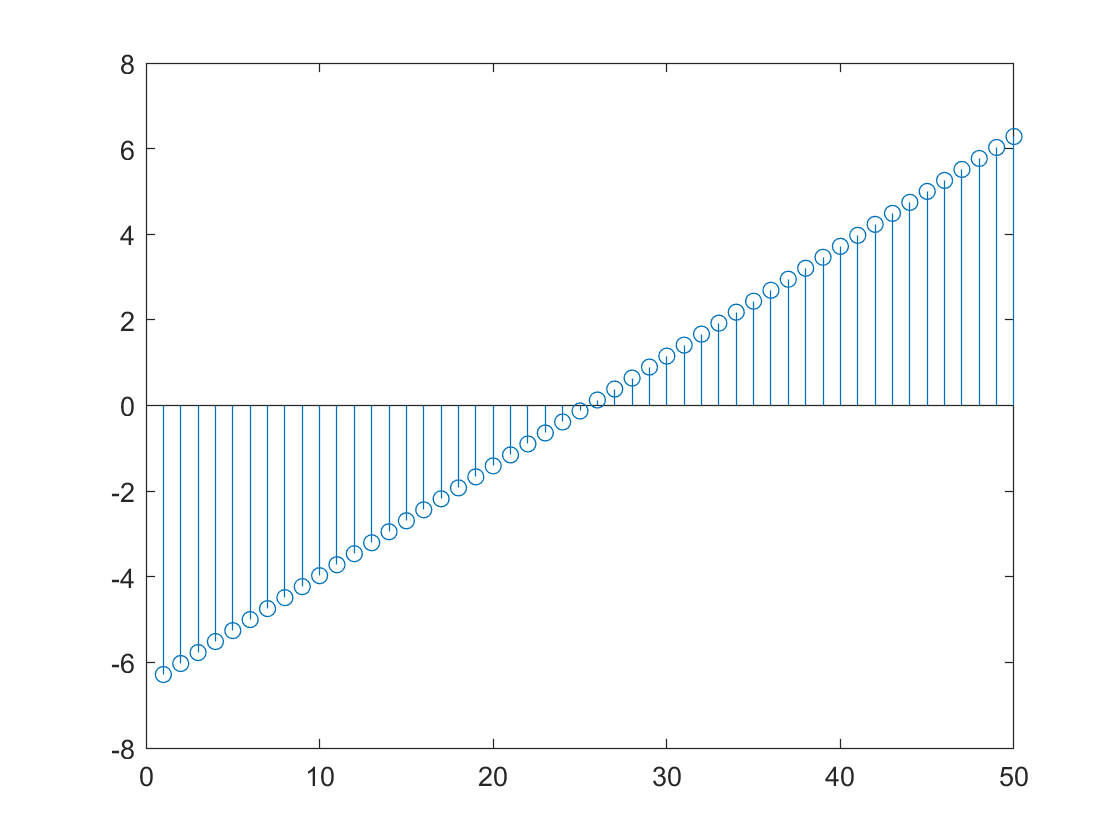

stem(Y)

## Customizations

### Plot Multiple Data Sets at Unique Positions

Plot 50 data values of sine and cosine evaluated at different sets of *x* values. Specify the data and corresponding sets of *x* values for each series as column vectors which are then concatenated into an array. Stem plots each individual column of the procided array as a seperate set of data.

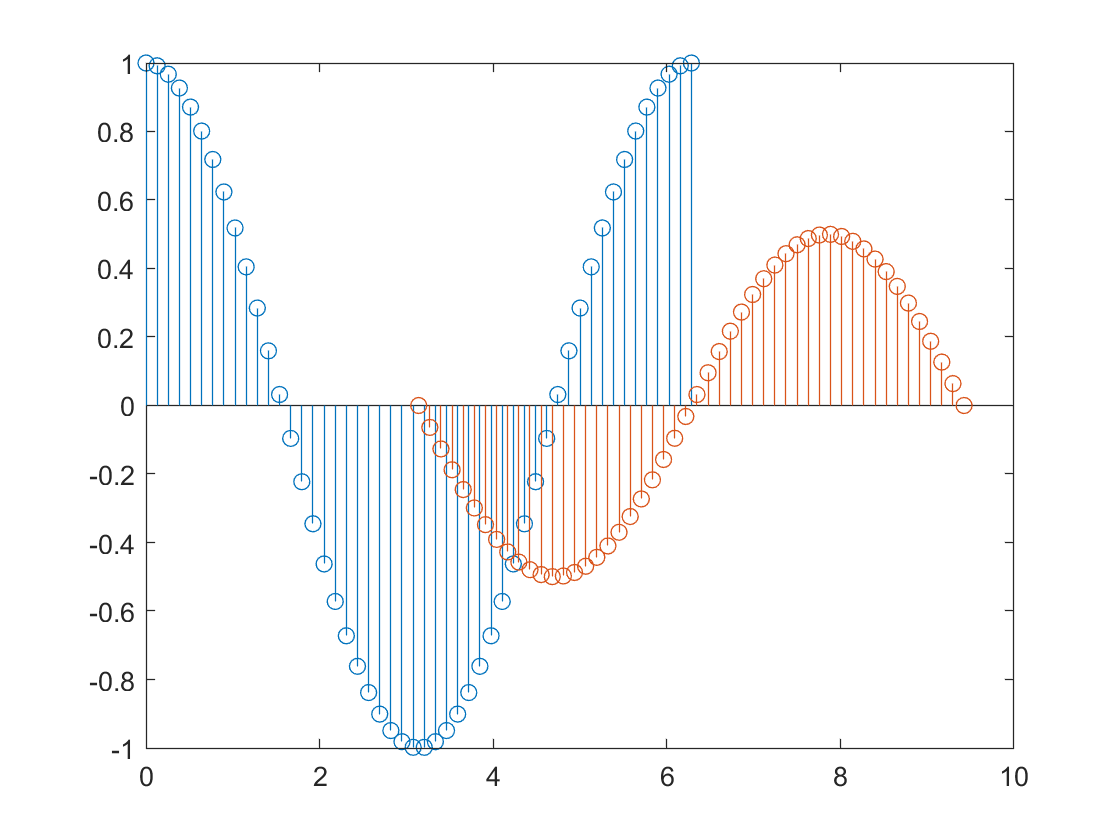

x1 = linspace(0,2*pi,50)';
x2 = linspace(pi,3*pi,50)';
X = [x1, x2];
Y = [cos(x1), 0.5*sin(x2)];
stem(X,Y)

### Specify Stem and Marker Options 

The connecting stem lines and marker points can be set to various colors, shapes, and thicknesses using the following plot property name value pairs.

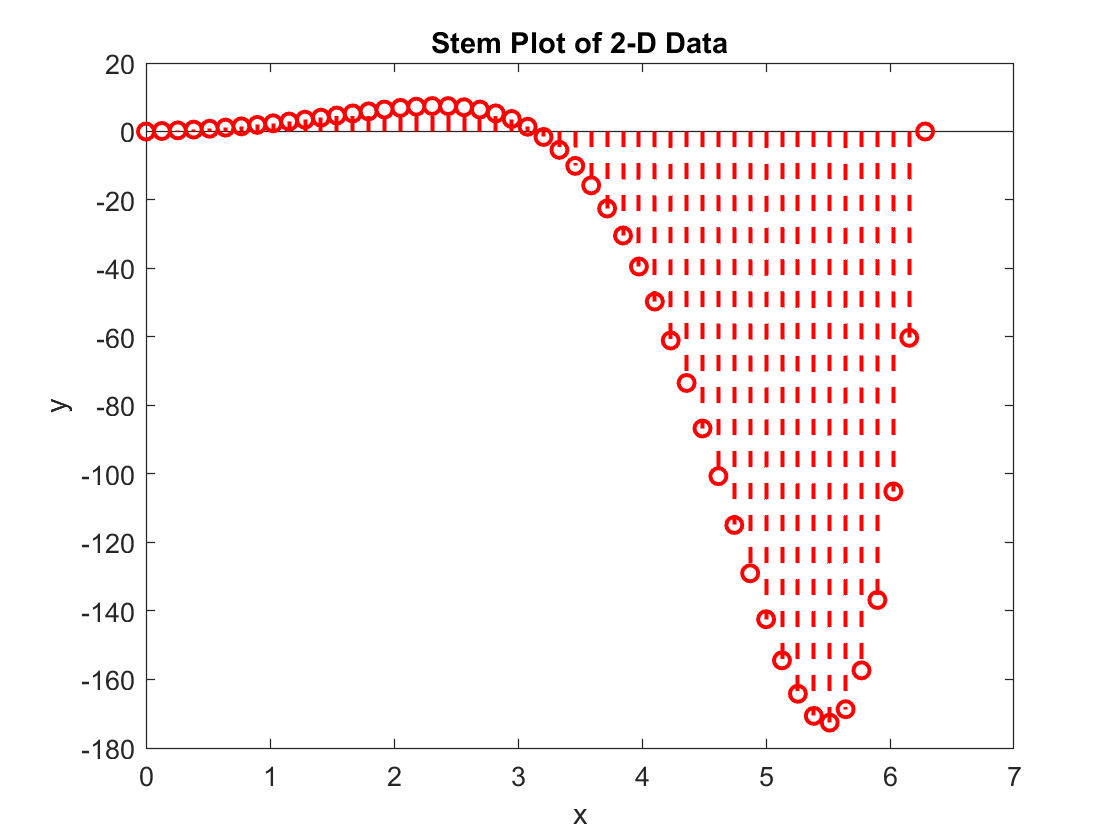

MarkerType = 'o';
LineWidth = 1.5;
StemLineStyle = '--';
Color = "red";

X = linspace(0,2*pi,50)';
Y = (exp(X).*sin(X));
st = stem(X,Y,...
    "Marker",MarkerType,...         % Specify the point symbol
    "LineWidth",LineWidth,...       % Specify stem line width
    "LineStyle",StemLineStyle,...   % Specify stem line appearance
    "Color",Color);                 % Specify the plot color

title("Stem Plot of 2-D Data")
xlabel('x')
ylabel('y')
zlabel('z')

## Additional Information

### Get All Stem Properties

Graphics objects in MATLAB have many properties. To see all the properties of a stem, uncomment the following code

% get(st)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[stem](https://www.mathworks.com/help/matlab/ref/stem.html)